# LQR Design for the Linearized System

% Given Parameters
M = 1000; % Crane mass
m1 = 100; % Load 1 mass
m2 = 100; % Load 2 mass
l1 = 20;  % Cable length of Load 1
l2 = 10;  % Cable length of Load 2
g =  9.81; 

% Substituting the given values of the parameters in A and B matrices
% respectively.

A=[0 1 0 0 0 0;
   0 0 -(m1*g)/M 0 -(m2*g)/M 0;
   0 0 0 1 0 0;
   0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
   0 0 0 0 0 1;
   0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];

B=[0; 1/M; 0; 1/(M*(l1)); 0; 1/(M*l2)];

% Calculating the controllability Matrix using the built-in Matlab Function
% ctrb
Controllability = ctrb(A,B)

Controllability = 1.0e-03 *

         0    1.0000         0   -0.1472         0    0.1419
    1.0000         0   -0.1472         0    0.1419         0
         0    0.0500         0   -0.0319         0    0.0227
    0.0500         0   -0.0319         0    0.0227         0
         0    0.1000         0   -0.1128         0    0.1249
    0.1000         0   -0.1128         0    0.1249         0


if (rank(Controllability)==6)
    disp("Controllability Matrix is full rank, so the linearized system is controllable.")
else
    disp("Controllability Matrix is Rank Deficient, so the linearized system is uncontrollable.")
end

Controllability Matrix is full rank, so the linearized system is controllable.


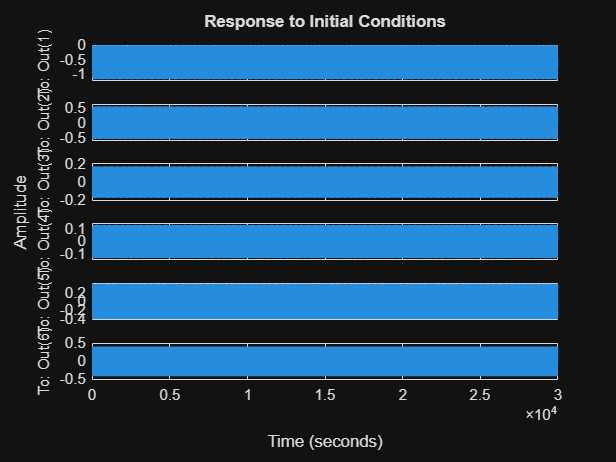

% Taking the initial conditions as:
X_0 = [0;0;deg2rad(10);0;deg2rad(20);0]; 

% Assuming the values for Q and R

Q=[100 0 0 0 0 0;
   0 100 0 0 0 0;
   0 0 100 0 0 0;
   0 0 0 100 0 0;
   0 0 0 0 100 0;
   0 0 0 0 0 100];
R=0.1;
% Q and R matrices are a part of the cost function that is
% defined in the LQR controller  
% We need to have a trade-off between Q and R so in order to develop a
% system based on our liking, Q is a penalty on Errors, while R is a
% penalty on control effort

% Assumption: I've assumed C to be a 6x6 Identity Matrix and D = 0 which
% means the ouput is only the function of state vector.
C = eye(6);
D = 0; 
system1 = ss(A,B,C,D);
% ss is the in-built MATLAB function  for calculating the state space representation of the system
figure
initial(system1,X_0)
% initial - MATLAB inbuilt function to check the initial response of the system
grid on  

disp("When the LQR controller (with Q and R designed earlier) is taken into consideration for the linearized system")

When the LQR controller (with Q and R designed earlier) is taken into consideration for the linearized system


[K_Gain_mat, Po_def_mat, Poles] = lqr(system1,Q,R); % MATLAB function for LQR Controllers
K_Gain_mat 

K_Gain_mat =    31.6228  276.7524  -31.7204 -357.5875  -15.2431 -179.6351


Po_def_mat  

Po_def_mat = 1.0e+05 *

    0.0088    0.0378   -0.0113   -0.0612   -0.0057   -0.0311
    0.0378    0.3325   -0.0378   -0.5587   -0.0186   -0.2782
   -0.0113   -0.0378    1.2834    0.0634    0.0043    0.0287
   -0.0612   -0.5587    0.0634    3.3087    0.0355    0.3564
   -0.0057   -0.0186    0.0043    0.0355    0.6190    0.0156
   -0.0311   -0.2782    0.0287    0.3564    0.0156    0.8079


Poles 

Poles =   -0.0020 + 0.7285i
  -0.0020 - 0.7285i
  -0.0033 + 1.0429i
  -0.0033 - 1.0429i
  -0.1152 + 0.1144i
  -0.1152 - 0.1144i


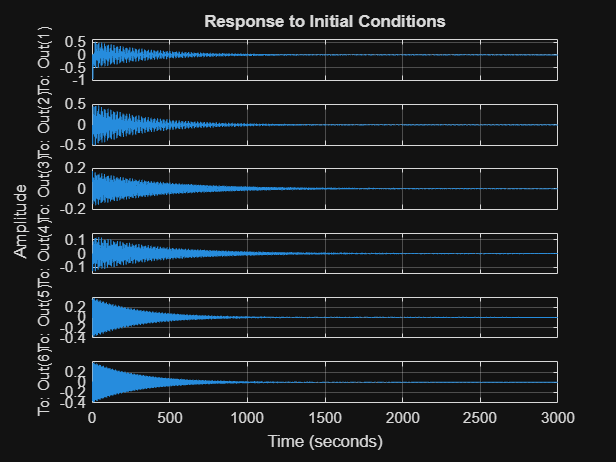

system_2 = ss(A-(B*K_Gain_mat),B,C,D); % Using the K matrix to define the State Space
figure
initial(system_2,X_0)
grid on

disp("Increasing the Q value leads to tighter accuracy and faster convergence.");

Increasing the Q value leads to tighter accuracy and faster convergence.


disp("Decreasing the R value leads to faster response but consumes a lot of control effort and is therefore expensive.");

Decreasing the R value leads to faster response but consumes a lot of control effort and is therefore expensive.
